clc; clear; clf;

deltaT = 0.1;

Kalman1.x = [0];
Kalman1.P = [0];
Kalman1.F = [1];
Kalman1.B = [deltaT];
Kalman1.Q = [0.1];
Kalman1.H = [1];
Kalman1.R = [1];

Data = readtable("MagTest2.xlsx");
Data.ThetaMag = atan2d(Data.MagY,Data.MagX)-119.3557

Data = 358×5 table
     Time      GyroZ      MagY      MagX       ThetaMag 
    ______    _______    ______    _______    __________

    21.975       0.39     93.75     -52.73    2.2364e-05
    22.021      0.514     93.75     -52.73    2.2364e-05
    22.068      0.562     93.75     -52.73    2.2364e-05
    22.115    0.58273     92.58     -52.73       0.30847
    22.161      0.466     92.58     -52.73       0.30847
    22.208    0.50091    93.005     -52.73       0.19563
    22.254      0.416     93.75     -52.73    2.2364e-05
      22.3      0.442     93.75     -52.73    2.2364e-05
    22.346      0.453     93.75    -54.375       0.75803
    22.391      0.538     93.75     -55.08        1.0794
    22.437    0.46727     93.75     -55.08        1.0794
    22.483      0.465     93.75     -55.08        1.0794
    22.528  

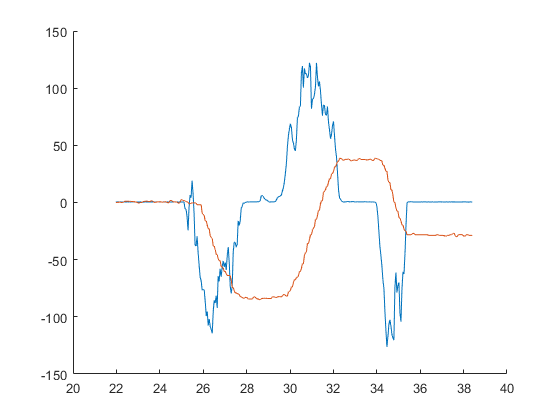

figure;
hold on
plot(Data.Time,Data.GyroZ)
plot(Data.Time,Data.ThetaMag)
hold off

for i = 1:size(Data.Time)
    if(i == 1)
        Kalman1.x = [0];
        Kalman1.P = [0];
    else
        Kalman1.B = Data.Time(i) - Data.Time(i-1);
        [Kalman1.x,Kalman1.P] = Prediction(Kalman1.x,Kalman1.P,Kalman1.F,Kalman1.B,Kalman1.Q,Data.GyroZ(i));
        Data.GyroTheta(i) = Kalman1.x;
        [Kalman1.x,Kalman1.P] = Update(Kalman1.x,Kalman1.P,Kalman1.H,Kalman1.R,Data.ThetaMag(i));
        Data.FilteredTheta(i) = Kalman1.x;
    end
end

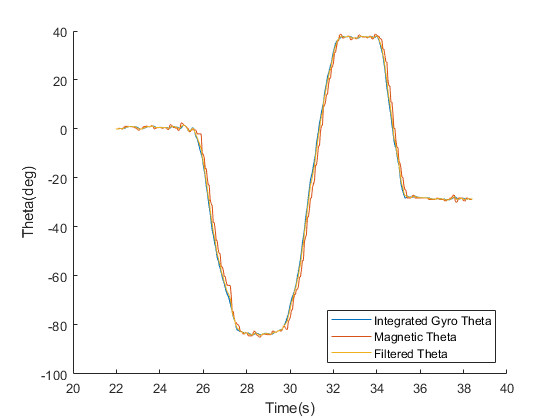

figure;
hold on
plot(Data.Time,Data.GyroTheta)
plot(Data.Time,Data.ThetaMag)
plot(Data.Time,Data.FilteredTheta)
legend("Integrated Gyro Theta","Magnetic Theta","Filtered Theta","Location","southeast")
hold off
xlabel("Time(s)")
ylabel("Theta(deg)")

function [x_predicted,P_predicted] = Prediction(x_prev,P_prev,F,B,Q,u)
    x_predicted = F*x_prev+B*u;
    P_predicted = F*P_prev*transpose(F) + Q;
end
function [x_updated,P_updated] = Update(x,P,H,R,z)
    K_updated = P*transpose(H)/(H*P*transpose(H)+R);
    x_updated = x + K_updated*(z - H*x);
    P_updated = P - K_updated*H*P;
end